clc;clear;
res = xlsread('F:\大四\数据集.xlsx');
%%  数据分析
num_size = 0.8;                              % 训练集占数据集比例
t = 1;                                       % 输出变量最后一列为输出
num_samples = size(res, 1);                  % 样本个数
res = res(randperm(num_samples), :);         % 打乱数据集（不希望打乱时，注释该行）
num_train_s = round(num_size * num_samples); % 训练集样本个数
x = size(res, 2) - t;                        % 输入变量特征维度

%% 划分训练集和测试集

P_train = res(1: num_train_s, 1: x)';     %训练输入
T_train = res(1: num_train_s, x + 1: end)';  %训练输出
m = size(P_train, 2);

P_test = res(num_train_s + 1: end, 1: x)';
T_test = res(num_train_s + 1: end, x + 1: end)';
n = size(P_test, 2);

inputnum=size(P_train,1);       % 输入层神经元个数
outputnum=size(T_train,1);      % 输出层神经元个数=偏置个数
hiddennum=55; % 隐含层神经元个数
w1num=inputnum*hiddennum; % 输入层到隐层的w个数
w2num=outputnum*hiddennum;% 隐含层到输出层的w个数
N=w1num+hiddennum+w2num+outputnum;%自变量的总数

%%  数据归一化
[p_train, ps_input] = mapminmax(P_train, 0, 1);
p_test = mapminmax('apply', P_test, ps_input);

[t_train, ps_output] = mapminmax(T_train, 0, 1);
t_test = mapminmax('apply', T_test, ps_output);

%%  创建模型
activate_model = 'sig';  % 激活函数
[IW, B, LW, TF, TYPE] = elmtrain(p_train, t_train, hiddennum, activate_model, 0);
%% 通过初始样本数据集X建立新的训练样本
%将初始样本数据集X中每个自变量的指标值增加10%得到新的训练样本Q。
%将初始样本数据集X中第i个指标的值增加10%,且其他自变量的值保持不变所构成的样本数据集用Qi表示。
p=p_train;
%varNum = size( inputData,1);    % 变量个数
% ======用训练好的网络计算各个变量的MIV值=====================
p=p';
[m,n]=size(p);
yy_temp=p;
% p_increase为增加10%的矩阵 p_decrease为减少10%的矩阵
for i=1:n
    p=yy_temp;
    pX=p(:,i);
    pa=pX*1.1;
    p(:,i)=pa;
    aa=['p_increase'  int2str(i) '=p;'];
    eval(aa);
end
for i=1:n
    p=yy_temp;
    pX=p(:,i);
    pa=pX*0.9;
    p(:,i)=pa;
    aa=['p_decrease' int2str(i) '=p;'];
    eval(aa);
end

%%  仿真测试
% 转置后sim

for i=1:n
    eval(['p_increase',num2str(i),'=transpose(p_increase',num2str(i),');'])
end
for i=1:n
    eval(['p_decrease',num2str(i),'=transpose(p_decrease',num2str(i),');'])
end

for i=1:n
    bb=['result_in',num2str(i), '= elmpredict(p_increase',num2str(i),',IW, B, LW, TF, TYPE);']; %加
    eval(bb)
end
for i=1:n
    cc=['result_de',num2str(i), '= elmpredict(p_decrease',num2str(i),',IW, B, LW, TF, TYPE);']; %加
    eval(cc)
end

for i=1:n
    IV= ['result_in',num2str(i), '-result_de',num2str(i)];
    eval(['MIV_',num2str(i) ,'=mean(',IV,')',';']) ;
    eval(['MIVX=', 'MIV_',num2str(i),';']);
    MIV(i,:)=abs(MIVX);
end
[MB,iranked] = sort(MIV,'descend');
total_MIV=sum(MB);
%计算每个自变量对miv的贡献比例
contribution_ratio = MB / total_MIV;
%输出结果
disp('每个自变量对miv的贡献比例:');

每个自变量对miv的贡献比例:


disp(contribution_ratio);

    0.5063
    0.4905
    0.0008
    0.0007
    0.0007
    0.0006
    0.0003




%初始化累计贡献率为0
cumulative_rate = 0;
%遍历数据，计算每个时间点的累计贡献率
for i = 1:length(MB)
cumulative_value = sum(MB(1:i));
cumulative_rate = (cumulative_value / total_MIV)*100;
fprintf('累计贡献率: %.2f%% ', cumulative_rate);
end

累计贡献率: 50.63% 累计贡献率: 99.68% 累计贡献率: 99.76% 累计贡献率: 99.84% 累计贡献率: 99.90% 累计贡献率: 99.97% 累计贡献率: 100.00% 

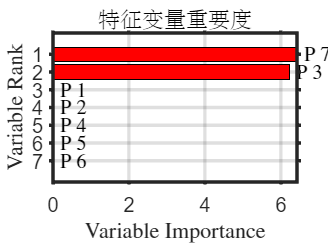



%% 数据可视化分析
%%
%-------------------------------------------------------------------------------------
figure(1)
barh(MIV(iranked),'g');
xlabel('Variable Importance','FontSize',12,'Interpreter','latex');
ylabel('Variable Rank','FontSize',12,'Interpreter','latex');
title('特征变量重要度','fontsize',12,'FontName','华文宋体')
hold on
barh(MIV(iranked(1:3)),'y');
hold on
barh(MIV(iranked(1:3)),'r');
grid on 
xt = get(gca,'XTick');    
xt_spacing=unique(diff(xt));
xt_spacing=xt_spacing(1);    
yt = get(gca,'YTick');    
% 条形标注
for ii=1:length(MIV)
    text(...
        max([0 MIV(iranked(ii))+0.02*max(MIV)]),ii,...
        ['P ' num2str(iranked(ii))],'Interpreter','latex','FontSize',12);
end
set(gca,'FontSize',12)
set(gca,'YTick',yt);
set(gca,'TickDir','out');
set(gca, 'ydir', 'reverse' )
set(gca,'LineWidth',2);
grid on;

%drawnow
%[outputt,predict_label]  = ELM(iranked); %调用BP.m脚本，进行诊断
% %% 
% %-------------------------------------------------------------------------------------
iranked = iranked';
p_train=p_train';
p_test=p_test';
if sum(length(iranked)==[1,2,3,4,5,6,7])==7
    new_ptrain = p_train;
else
    ir = iranked(1:2);  %取重要度较高的前4个特征作为神经网络的输入
    new_ptrain = p_train(:,ir);
    new_ptest=p_test(:,ir);
end

rng('default')

new_ptrain = new_ptrain';
new_ptest=new_ptest';